%%%%%%%%%%%%%
% Preparation
%%%%%%%%%%%%%
e=1E-5;                 % Tolerance
n_array=[];             % Index sequence

% Jacobi method
time_ja=[];             % Running time
err_ja=[];              % Error

% QR method
time_qra=[];            % Running time
err_qra=[];             % Error

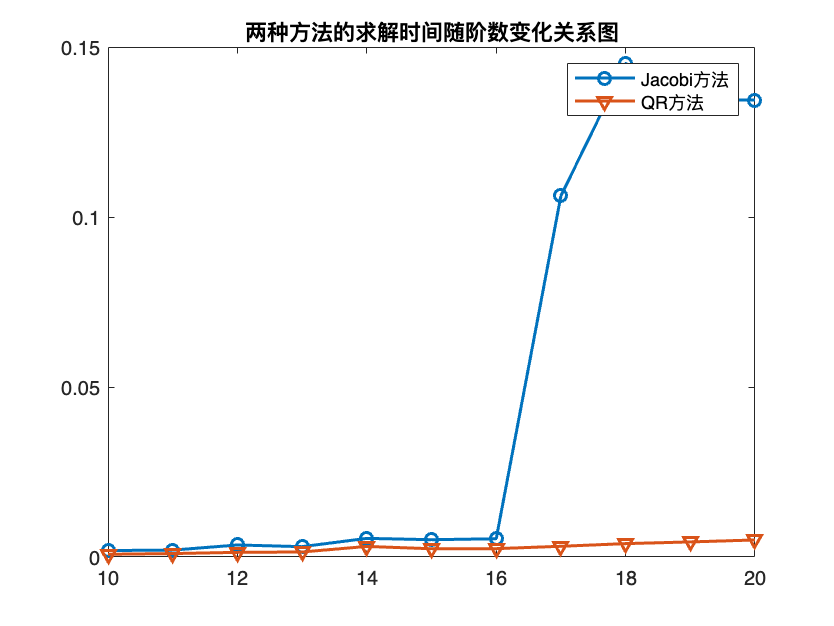

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The comparison between Jacobi method and QR method
% Pay attention to the running time and error.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n=10:1:20
    A=diag(repmat(2,1,n))...
    +diag(repmat(-1,1,n-1),1)...
    +diag(repmat(-1,1,n-1),-1);

    % True value
    real=eig(A);

    % Jacobi
    tic;
    [lambda1,times1]=eig_jacobi(A,e);
    lambda1=sort(lambda1);
    time_j=toc;
    time_ja(end+1)=time_j;
    err_ja(end+1)=norm(real-lambda1);

    % QR
    tic
    [lambda2,times2]=eig_qr(A,e);
    lambda2=sort(lambda2);
    time_q=toc;
    time_qra(end+1)=time_q;
    err_qra(end+1)=norm(real-lambda2);

    n_array(end+1)=n;
end

figure
plot(n_array,time_ja,'-o','Linewidth',1.5);hold on;
plot(n_array,time_qra,'-v','Linewidth',1.5);
legend("Jacobi方法","QR方法");
title('两种方法的求解时间随阶数变化关系图');

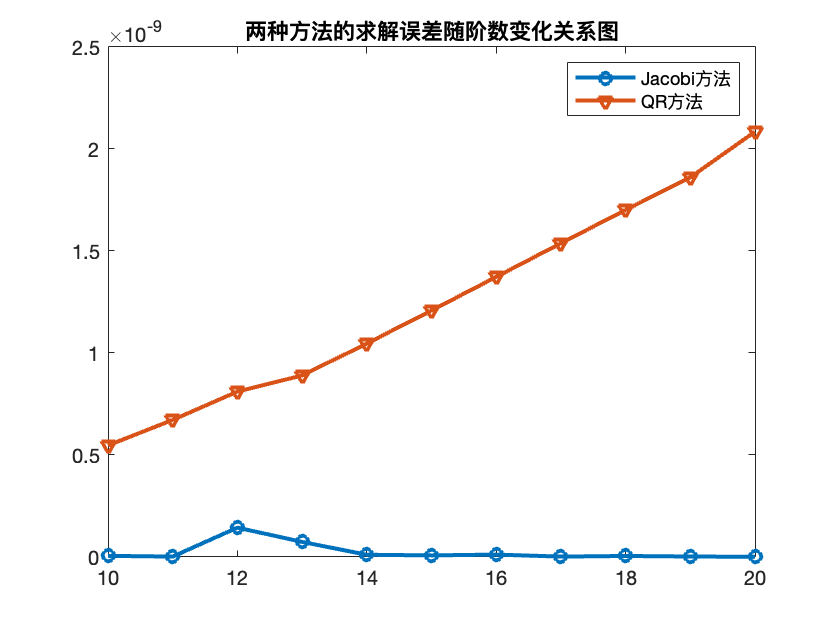


figure
plot(n_array,err_ja', "-o",'LineWidth',2);hold on;
plot(n_array,err_qra', "-v",'LineWidth',2);
legend("Jacobi方法","QR方法");
title('两种方法的求解误差随阶数变化关系图');

%%%%%%%%%%%%%%%%%%%%%%%%%%
% Inverse power method
% Choose 1 as Lambda0 (initial value), then pick one from [1.2,1.3], then
% pick any other value beside those mentioned as your initial value.
% Compare the result from the exact answer provided by function "eig" from
% MATLAB.
%%%%%%%%%%%%%%%%%%%%%%%%%%
A=diag(repmat(2,1,10))...
    +diag(repmat(-1,1,9),1)...
    +diag(repmat(-1,1,9),-1);
real=eig(A);
fprintf("The real eigenvalues of matrix A:\n");

The real eigenvalues of matrix A:


display(real);

real =     81.0140527710048e-003
    317.492934337638e-003
    690.278532109430e-003
    1.16916997399623e+000
    1.71537032345343e+000
    2.28462967654657e+000
    2.83083002600377e+000
    3.30972146789057e+000
    3.68250706566236e+000
    3.91898594722899e+000



% Choose 1
fprintf("Choose 1");

Choose 1

[lambda3,times3]=eig_invPow(A,1,e);

Not converged !

fprintf("The answer worked out by inv-pow method: %f",lambda3);

The answer worked out by inv-pow method: NaN


% Choose a value within [1.2,1.3]
fprintf("Choose a value from [1.2,1.3]");

Choose a value from [1.2,1.3]

lambda0=1.25;
[lambda4,times4]=eig_invPow(A,lambda0,e);
fprintf("The answer worked out by inv-pow method: %f",lambda4);

The answer worked out by inv-pow method: 1.330830


% Choose a value within [1.2,1.3]
fprintf("Choose another value");

Choose another value

lambda0=3;
[lambda5,times5]=eig_invPow(A,lambda0,e);

Not converged !

fprintf("The answer worked out by inv-pow method: %f",lambda5);

The answer worked out by inv-pow method: NaN


% The maximum eigenvalue
fprintf("The maximum eigenvalue");

The maximum eigenvalue

lambda0=inf;
[lambda6,times6]=eig_invPow(A,lambda0,e);
fprintf("The maximum eigenvalue: %f",lambda6);

The maximum eigenvalue: 3.682539


% The minimum eigenvalue
fprintf("The minimum eigenvalue");

The minimum eigenvalue

lambda0=-inf;
[lambda7,times7]=eig_invPow(A,lambda0,e);
fprintf("The minimum eigenvalue: %f",lambda7);

The minimum eigenvalue: 0.081014